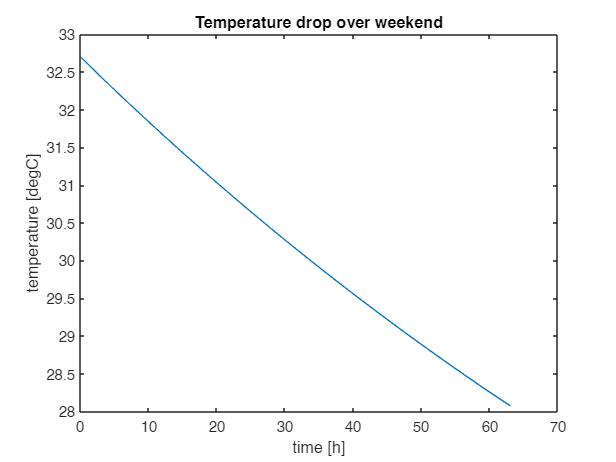

factor_weekend = 0;
Q_in_weekend =  factor_weekend * 1 * 10^3;

f_nacht_verwarmd = @(t_nacht,T_nacht) (Q_in_weekend-alpha * pool_area  *  ((T_nacht-273)-gebouw_temp_nacht) - pool_area*epsilon_mat*sigma*((T_nacht)^4- (gebouw_temp_nacht+273)^4))/(rho*volume*cpw);
[t_weekend_verwarmd, T_weekend_verwarmd] = ode45(f_nacht_verwarmd, tspan_weekend, T0_weekend);
plot(t_weekend_verwarmd/3600, T_weekend_verwarmd-273)
xlabel('time [h]')
ylabel('temperature [degC]')
title('Temperature drop over weekend')